clear;
clc;
clf;


%此程序用于生成光子筛以及公式法计算离轴光子筛
t1=clock;
f1=2;%记住单位是m米
D1=0.1;
lamda1=632.8e-9;
k1=2*pi/lamda1;
eta1=1.53;
N1=N(D1,lamda1,f1);%算总环数
number=0;   %计数用
cita=90%.5/3600;%角度单位度,先假设入射光与x轴垂直吧,可以在yoz平面看

cita = 90

gn=0;%gn,hn实际就是光线与x,y轴的cos值
hn=cosd(cita);
%N1=19041;测试数据
para=zeros([4,N1]);
%创造每一环的参数
%环半径1
%环宽度2
%每一环的孔径数3
%每一环孔径的直径4
for i=1:N1
    epsilon=0.5;%*win_m(i+N1,2*N1);
    para(1,i)=r_m(i,lamda1,f1);
    para(2,i)=w_m(para(1,i),lamda1,f1);
    para(3,i)=N_m(epsilon,eta1,para(1,i),para(2,i));
    para(4,i)=eta1*para(2,i);
    number=number+para(3,i);
end    

save sample1_para para  N1 number
%PMIR=    %用于存放每一个产出的孔径

hole=zeros(3,number,'single');
number1=1;
for i=1:N1
    r_m1=para(1,i);
    w_m1=para(2,i);
    N_m1=para(3,i);
    d=para(4,i);
    for j=0:2*pi/N_m1:2*pi*(N_m1-1)/N_m1
        x=r_m1*cos(j);
        y=r_m1*sin(j);
        hole(:,number1)=[x y d/2];
        number1=number1+1;
    end
end
%hole1=hole(:,1:number1-1);%测试用

save sample1_hole.mat hole

t2=clock;
etime(t2,t1)

ans = 2.6660

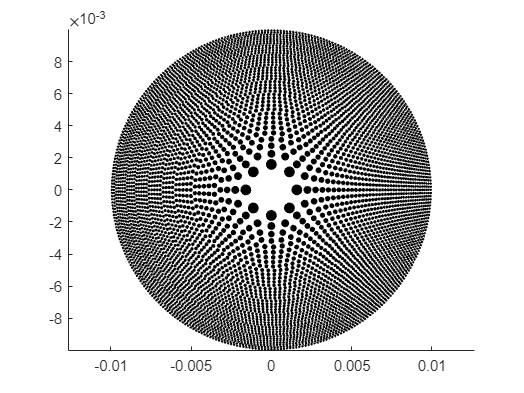

%此节用于生成光子筛展示用图样,只是看看用的(资源大户警告!!!)
%clf
%for i=1:number
%    rectangle('Position',[hole(1,i)-hole(3,i),hole(2,i)-hole(3,i),hole(3,i)*2,hole(3,i)*2],'FaceColor','k',...
%        'EdgeColor','k','Curvature',[1 1])
%end    
%axis equal 

%以下使用公式法计算离轴光子筛(CPU)

X=meshgrid(-1e-4:5e-7:1e-4);
Y=meshgrid(-1e-4:5e-7:1e-4).';
size1=size(X,1);
U1=zeros(size1,size1);

delta_t=0;

if number<1000
    t1=clock;
    for i=1:number
        an=double(hole(3,i));
        xn=double(hole(1,i));
        yn=double(hole(2,i));
        U1=U1+U_n(X=X,Y=Y,k=k1,An=1,f=f1,Ln=0,an=an,xn=xn,yn=yn,gn=gn,hn=hn);
    end
    t2=clock;
    delta_t=etime(t2,t1)
    disp(['time ',num2str(delta_t),' s'])

else
    t1=clock;
    for i=1:1000
        an=double(hole(3,i));
        xn=double(hole(1,i));
        yn=double(hole(2,i));
        U1=U1+U_n(X,Y,k1,1,f1,0,an,xn,yn,gn,hn);
    end
    t2=clock;
    delta_t=etime(t2,t1);
    disp(['estimated time ',num2str(number*delta_t/1000),' s'])
    pause;
    for i=1000:number
        an=double(hole(3,i));
        xn=double(hole(1,i));
        yn=double(hole(2,i));
        U1=U1+U_n(X,Y,k1,1,f1,0,an,xn,yn,gn,hn);
    end
end

estimated time 37650.7979 s


%以下使用公式法计算离轴光子筛(CPU并行)

X=meshgrid(-1e-4:5e-7:1e-4);
Y=meshgrid(-1e-4:5e-7:1e-4).';
size1=size(X,1);
U1=zeros(size1,size1);

delta_t=0;

if number<1000
    t1=clock;
    parfor i=1:number
        an=double(hole(3,i));
        xn=double(hole(1,i));
        yn=double(hole(2,i));
        U1=U1+U_n(X=X,Y=Y,k=k1,An=1,f=f1,Ln=0,an=an,xn=xn,yn=yn,gn=gn,hn=hn);
    end
    t2=clock;
    delta_t=etime(t2,t1)
    disp(['time ',num2str(delta_t),' s'])

else
    t1=clock;
    parfor i=1:1000
        an=double(hole(3,i));
        xn=double(hole(1,i));
        yn=double(hole(2,i));
        U1=U1+U_n(X,Y,k1,1,f1,0,an,xn,yn,gn,hn);
    end
    t2=clock;
    delta_t=etime(t2,t1);
    disp(['estimated time ',num2str(number*delta_t/1000),' s'])
    pause;
    parfor i=1000:number
        an=double(hole(3,i));
        xn=double(hole(1,i));
        yn=double(hole(2,i));
        U1=U1+U_n(X,Y,k1,1,f1,0,an,xn,yn,gn,hn);
    end
end

estimated time 44694.8049 s


%以下使用公式法计算离轴光子筛(GPU)

X=meshgrid(-1e-4:5e-7:1e-4);
Y=meshgrid(-1e-4:5e-7:1e-4).';
X_gpu=gpuArray(X);
Y_gpu=gpuArray(Y);
size1=size(X,1);
U1=gpuArray(zeros(size1,size1));

delta_t=0;

if number<1000
    t1=clock;
    for i=1:number
        an=double(hole(3,i));
        xn=double(hole(1,i));
        yn=double(hole(2,i));
        U1=U1+U_n(X=X,Y=Y,k=k1,An=1,f=f1,Ln=0,an=an,xn=xn,yn=yn,gn=gn,hn=hn);
    end
    t2=clock;
    delta_t=etime(t2,t1)
    disp(['time ',num2str(delta_t),' s'])

else
    t1=clock;
    for i=1:1000
        an=double(hole(3,i));
        xn=double(hole(1,i));
        yn=double(hole(2,i));
        U1=U1+U_n(X,Y,k1,1,f1,0,an,xn,yn,gn,hn);
    end
    t2=clock;
    delta_t=etime(t2,t1);
    disp(['estimated time ',num2str(number*delta_t/1000),' s'])
    pause;
    for i=1000:number
        an=double(hole(3,i));
        xn=double(hole(1,i));
        yn=double(hole(2,i));
        U1=U1+U_n(X,Y,k1,1,f1,0,an,xn,yn,gn,hn);
    end
end

estimated time 39637.0557 s


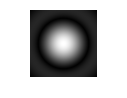

U1=abs(U1);
U1_max=max(max(U1));
imshow(U1/U1_max)


%RI = imref2d(size(U1));
%RI.XWorldLimits = [-2e-5 2e-5];
%RI.YWorldLimits = [-2e-5 2e-5];
figure
%plot(0:1e-7:2e-5,U3R/max(U3R))
%U2=zeros(size1,size1);

%测试代码
U1_max=max(max(U1));

function r=r_m(m,lamda,f)   %算环带半径
    r=(m^2*lamda^2+2*m*lamda*f)^0.5;
end

%算环带间隔,明带,自变量明带半径
function w=w_m(R,lamda,f)
    w=lamda*f/(2*R);
end

%算环带数
function n=N(D,lamda,f)
    n=fix(D*D/(8*f*lamda));
end

%按照指定填充因子计算m环孔径数
function N=N_m(epsilon,eta,r_m0,w_m0)
    N=fix(epsilon*2*pi*r_m0/(eta*w_m0));
end
%"大口径光子筛小孔环带设计方法研究_周润"高斯窗等距切趾,0.4是高斯参数
function win1=win_m(n,N)
    win1=exp(-0.5*((n-0.5*(N-1))/(0.5*0.5*(N-1)))^2);
end

%以下用来算相位面
function U1=U_n(X,Y,k,An,q,Ln,an,xn,yn,gn,hn)
%非近轴,远场,孔很小的情况(条件我尚未量化)
%An孔径中心的振幅,近似代表整个,L_n,孔径中心的相位等效光程,(2.24)
    H=(q^2+(X-xn).^2+(Y-yn).^2).^0.5;
    rou=((X-xn-gn.*H).^2+(Y-yn-hn.*H).^2).^0.5;
    U1=(k*An*q*an^2./(H.^2)).*exp(1j*k*(H+Ln)).*besselj(1,k*an*rou./H)./(k*an*rou./H);
end

function U2=U_m(Nm,k,Am,q,am,rm,R)
%以环带模型计算每环带的谱,记得考略环带模型的限制条件,以及后续可能需要评估一下精度误差
H0=(q^2+R.^2+rm^2).^0.5;
U2=Nm*k*Am*q*am^2./H0.^2.*besselj(1,k*am*rm./H0)./(k*am*rm./H0).*exp(1j*k*H0).*besselj(0,k*R*rm./H0);
end

%用来算倾斜的平面波,x,y类型没有要求,输出相应的相位
function Ln=tilt(cita,k,y)
    %tilt_light=exp(1i*k*(y*sind(cita)));
    Ln=y*sind(cita)
end